# 5.2 Display open-loop TF and closed loop TF with Controller

clear;
clc;
close all;
s = tf('s');


## 1a) Declaring the Transfer Functions

% Declaration of Transfer Function of the Plant
Vin = 5;
L = 42e-6;
C = 230e-6;
R_load = 20;
R_C = 0.5;
w0 = 1/sqrt(L*C) * sqrt(1/(1+R_C/R_load));
Q = (1/w0)*(1/((L/R_load)+C*R_C));
wz = 1/(R_C*C);

G = tf([Vin/wz, Vin], [1/w0^2, 1/(w0*Q), 1]); %-->here per numerator and denumerator

%Declaration of Transfer Function of the Sensor
R_vd1 = 22e3;
R_vd2 = 4.7e3;

K = tf(R_vd2/(R_vd1+R_vd2)); %-->here also per n and d

%Declaration of Transfer Function of the Controller
k_P = 6;
k_I = 180e3;

H = tf(k_P+k_I/s); %-->here per variable s

## 1b) Plotting the Transfer Functions

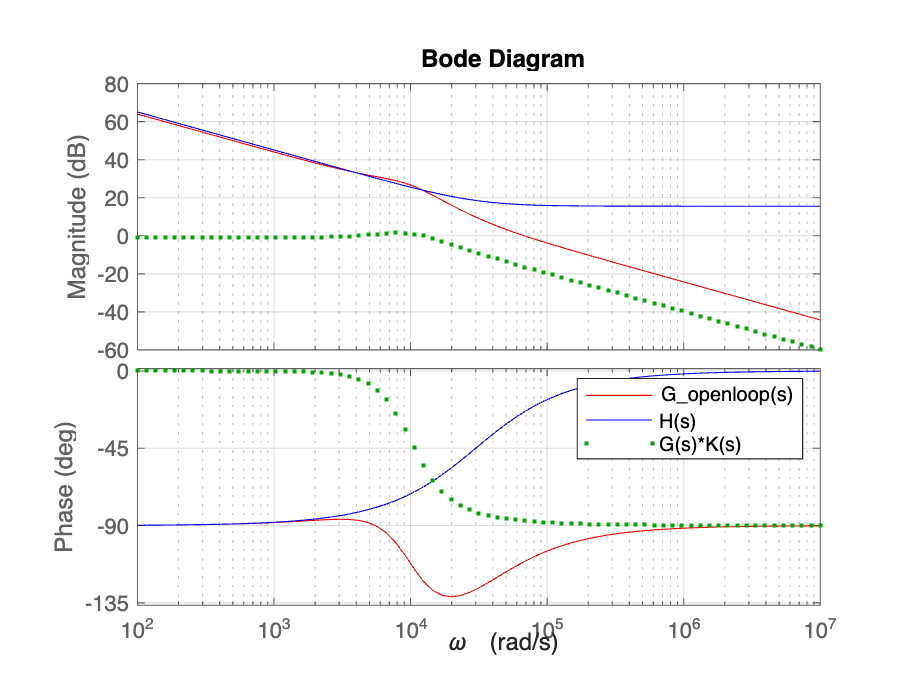

G_openloop = H*G*K;

figure;
hold on;
bode(G_openloop,'r', H,'b', G*K,'g.' ,{1e2, 1e7}); %bode-plot Open-loop
legend('G_openloop(s)', 'H(s)', 'G(s)*K(s)');
xlabel("\omega");
grid on;
hold off;

## 1c) Plotting the step response of the closed loop + bode plot

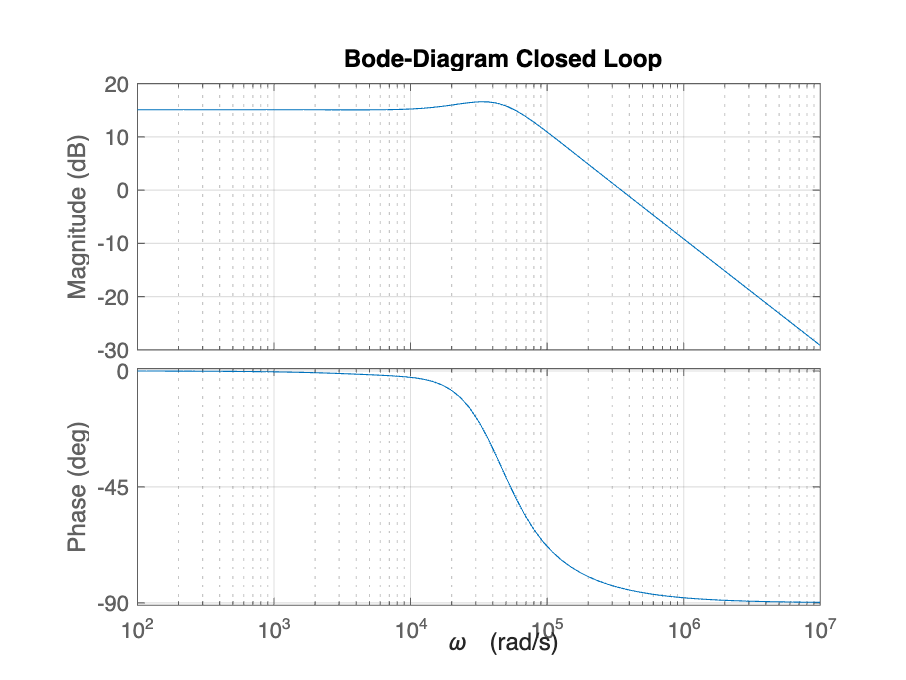

G_closedloop = (H*G)/(1+G_openloop);  %Vorwärtszweig/(1+Vorwärtszweig*Rückwärtszweig)

figure;
bode(G_closedloop, {1e2,1e7});
grid on;
xlabel('\omega');
title('Bode-Diagram Closed Loop')

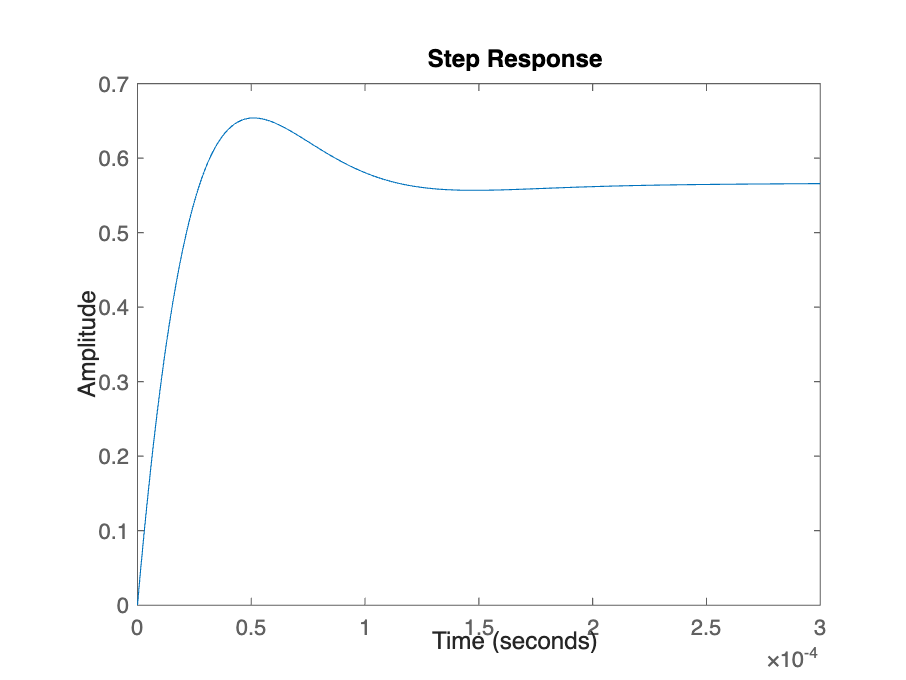


figure;
step(0.1*G_closedloop);

%Amplitude ist "Zuwachs" bei einem Sprung um 10%

## 3) Zero-Crossover Frequency and Phase Margin for kP and kI

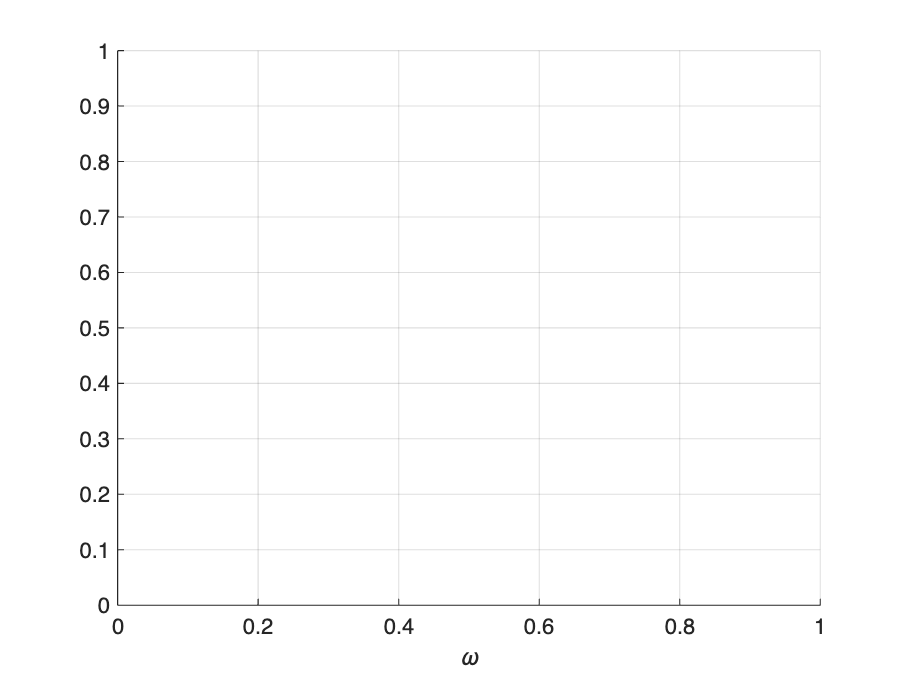

figure;
[Gm, Pm, Wcg, Wcp] = margin(G_openloop);
grid on;
xlabel("\omega");

fprintf('Crossover frequency: %0.7g Hz \n', Wcp/(2*pi));

Crossover frequency: 10826.48 Hz 


fprintf('Phase margin: %0.1f deg \n', Pm);

Phase margin: 69.0 deg 


## 4) Designing the digital controller

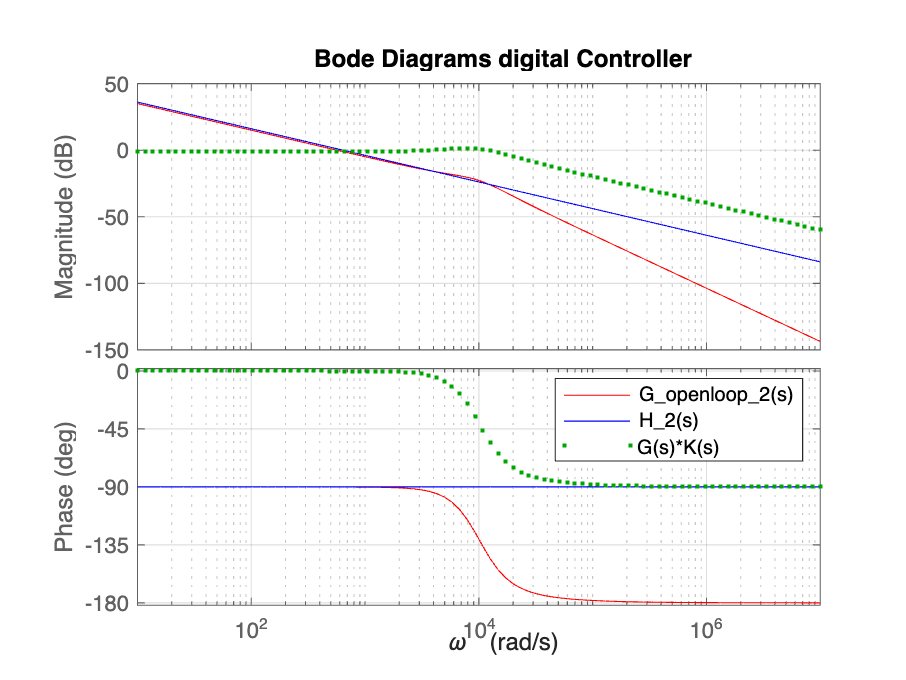

kI_2 = 641; %measured tsample_led = 200us, we take 220us for margin

H_2 = tf(kI_2/s);
G_openloop_2 = H_2*G*K;
G_closedloop_2 = (H_2*G)/(1+G_openloop_2);

%Bodeplot Openloop
figure;
hold on;
bode(G_openloop_2,'r', H_2,'b', G*K,'g.' ,{1e1, 1e7});
legend('G_openloop_2(s)', 'H_2(s)', 'G(s)*K(s)');
xlabel("\omega");
grid on;
title("Bode Diagrams digital Controller")
hold off;

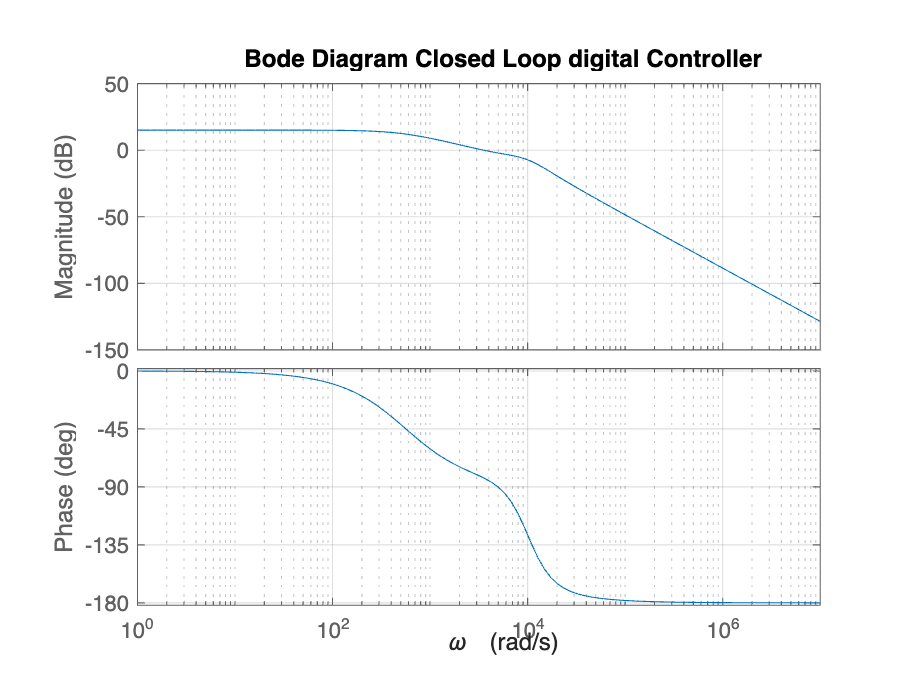


%Bodeplot Closedloop
figure;
hold on;
bode(G_closedloop_2 ,{1e0, 1e7});
xlabel("\omega");
grid on;
title("Bode Diagram Closed Loop digital Controller")
hold off;

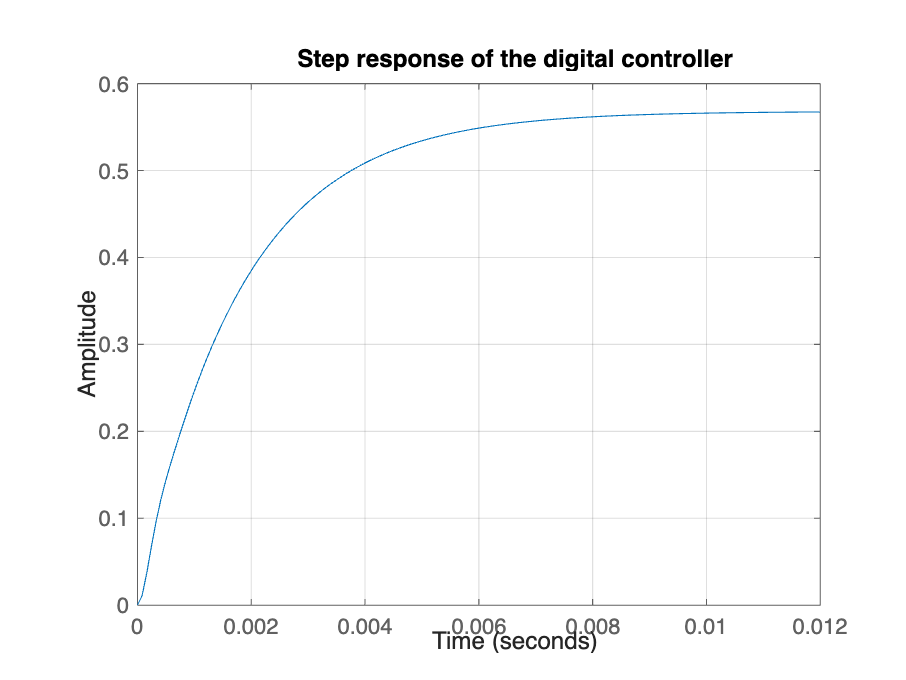


%Step response Closed loop_2
figure;
step(0.1*G_closedloop_2);
title("Step response of the digital controller");
grid on;



figure;
[Gm_2, Pm_2, Wcg_2, Wcp_2] = margin(G_openloop_2);
grid on;
xlabel("\omega");

fprintf('Crossover frequency: %0.6g Hz \n', Wcp_2/(2*pi));

Crossover frequency: 90.0695 Hz 


fprintf('Phase margin: %0.1f deg \n', Pm_2);

Phase margin: 89.9 deg 
